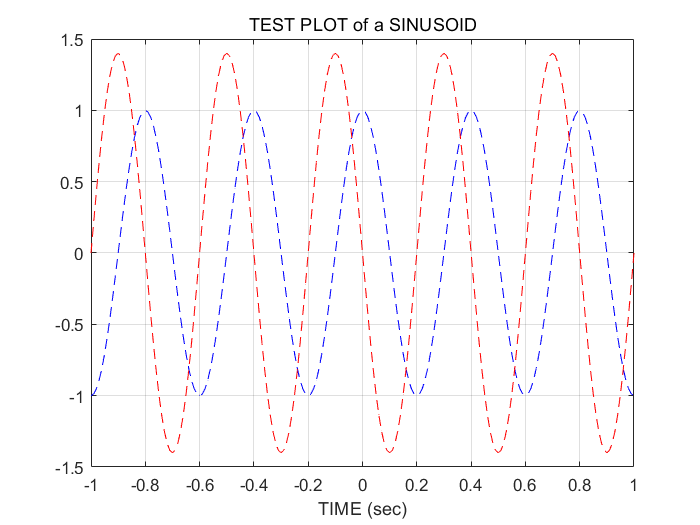

tt = -1:0.01:1;
xx = cos(5 * pi * tt);
zz = 1.4 * exp(j*pi/2)*exp(j*5*pi*tt);
plot(tt, xx, 'b--', tt, real(zz), 'r--');
grid on;
title('TEST PLOT of a SINUSOID');
xlabel('TIME (sec)');

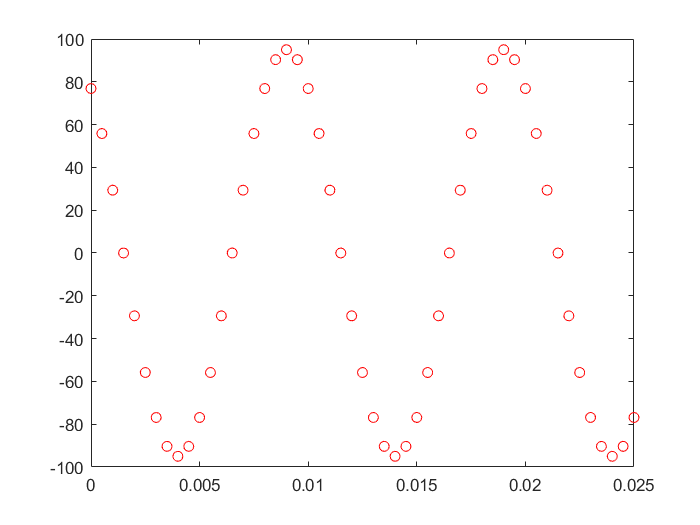

[tt, xx] = one_cos(95, 200 * pi, pi/5, 0.025);
plot(tt, xx, 'ro');

period = 1/4000;
interval = period / 25;
T = 0.05;
tt = -period:interval:period;

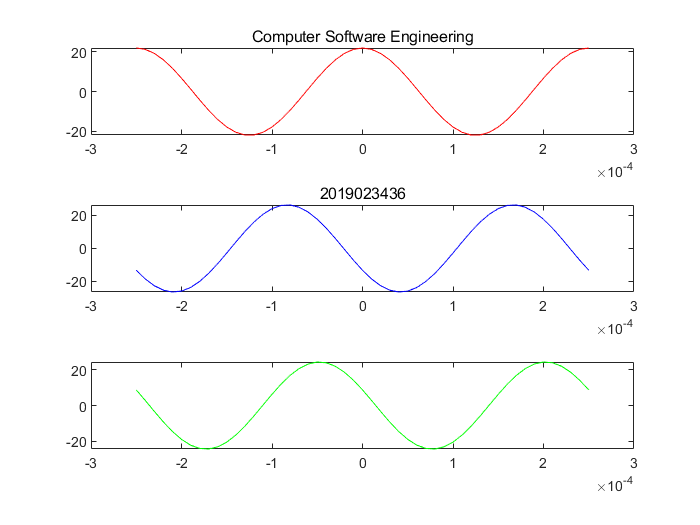

A1 = 22;
A2 = 1.2 * A1;
D = 3;
M = 8;
t_m1 = 37.2/M*T;
t_m2 = -41.3/D*T;

x1 = A1*cos(2*pi*4000*(tt - t_m1));
x2 = A2*cos(2*pi*4000*(tt - t_m2));

subplot(3, 1, 1);
plot(tt, x1, 'r');
title('Computer Software Engineering');
subplot(3, 1, 2);
plot(tt, x2, 'b');
title('2019023436');

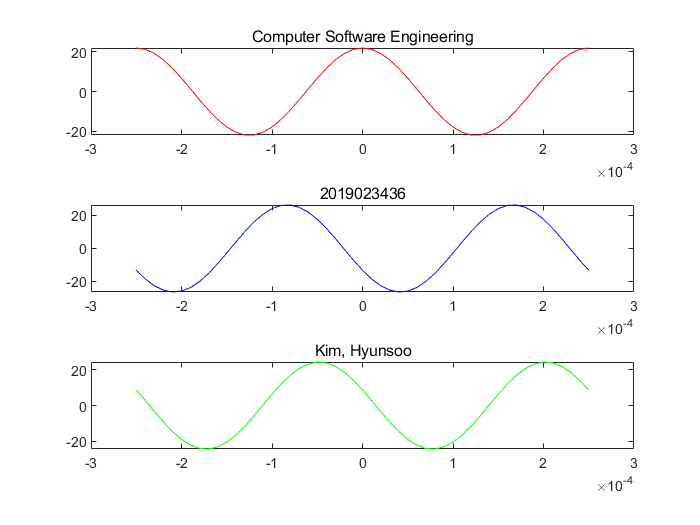

subplot(3, 1, 3);
x3 = x1 + x2;
plot(tt, x3, 'g');
title('Kim, Hyunsoo');

function [t, x] = one_cos(A, ohm, phi, dur)
    period = 2 * pi / ohm;
    interval = period / 20;
    t = 0 : interval : dur;
    x = A * cos(ohm * t + phi);
end

